HW3 Question 2

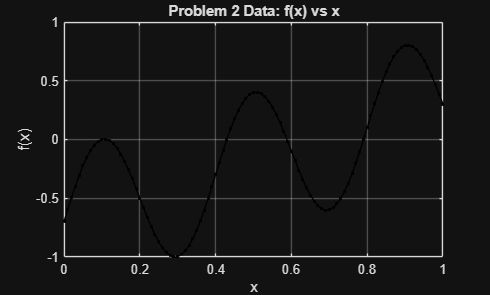

clear; clc; close all;


x = 0:0.01:1;                
y = load("problem2.txt"); 
y = y(:);                    
N = numel(y);
assert(numel(x) == N, 'x and y must have the same length (101).');


figure(1);
plot(x, y, 'k.-');
xlabel('x'); ylabel('f(x)');
title('Problem 2 Data: f(x) vs x');
grid on;

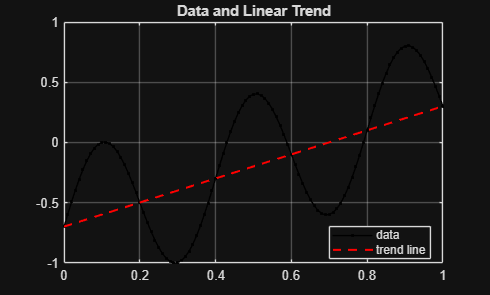



y0 = y(1);
y1 = y(end);
g = (y1 - y0) * x + y0;      

figure(2);
plot(x, y, 'k.-'); hold on;
plot(x, g, 'r--', 'LineWidth', 1.5);
legend('data', 'trend line', 'Location', 'best');
title('Data and Linear Trend');
grid on;

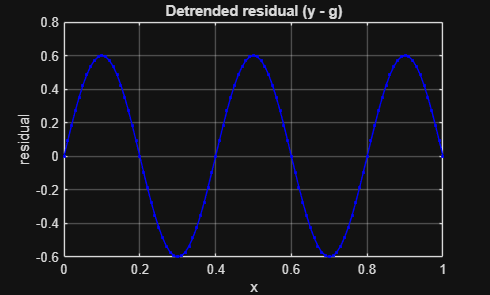



t = y - g.';                 % subtract column (transpose g to column)
figure(3);
plot(x, t, 'b.-');
xlabel('x'); ylabel('residual');
title('Detrended residual (y - g)');
grid on;


%% ----- Build design matrix for f(x) ≈ a1*x + a2*sin(6*pi*x) -----
M = [x.' sin(6*pi*x).'];     % N x 2 matrix
% Each column = basis function evaluated at x

%% ----- Solve normal equations -----
A = (M.' * M) \ (M.' * y);   % 2x1 coefficients

a1 = A(1);
a2 = A(2);
fprintf('Recovered model:\n');

Recovered model:


fprintf('  f(x) ≈ %.6f * x + %.6f * sin(6*pi*x)\n', a1, a2);

  f(x) ≈ 0.052210 * x + -0.100266 * sin(6*pi*x)



%% ----- Evaluate fitted model and residual -----
yhat = M * A;                % N×1 predicted values
err2 = norm(y - yhat, 2);

fprintf('  Residual 2-norm ||y - yhat||_2 = %.3e\n\n', err2);

  Residual 2-norm ||y - yhat||_2 = 5.189e+00



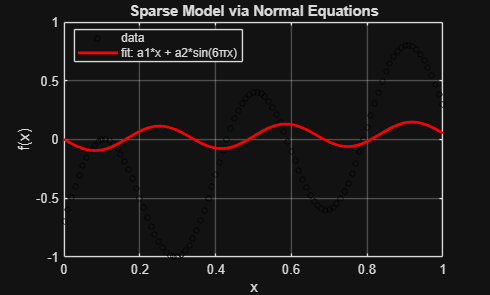


%% ----- Plot data vs. recovered model -----
figure(4);
plot(x, y, 'ko', 'MarkerSize', 4, 'DisplayName', 'data'); hold on;
plot(x, yhat, 'r-', 'LineWidth', 2, 'DisplayName', 'fit: a1*x + a2*sin(6πx)');
xlabel('x'); ylabel('f(x)');
title('Sparse Model via Normal Equations');
legend('Location','best');
grid on;